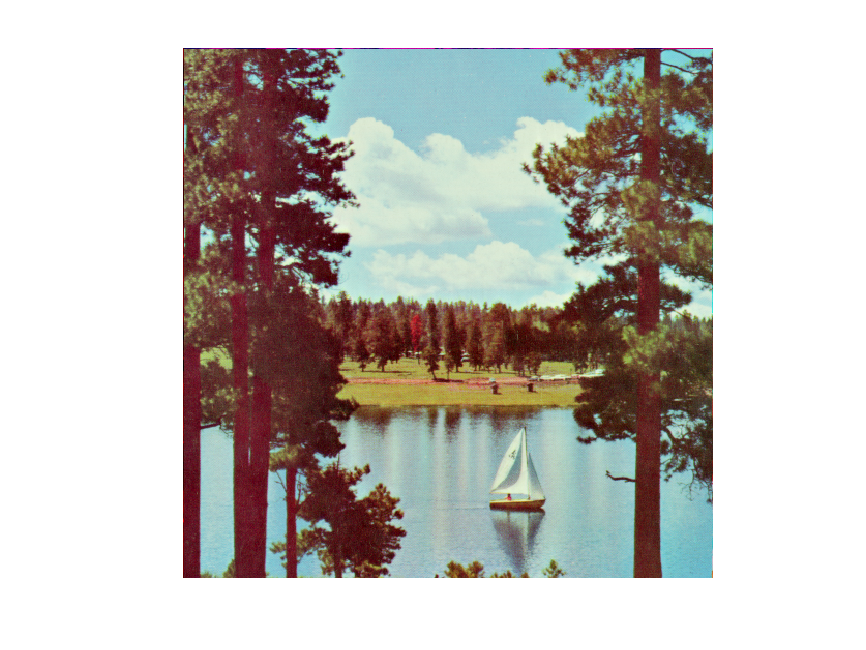

rgbImage = imread('sailboat_on_lake.tif');
imshow(rgbImage)

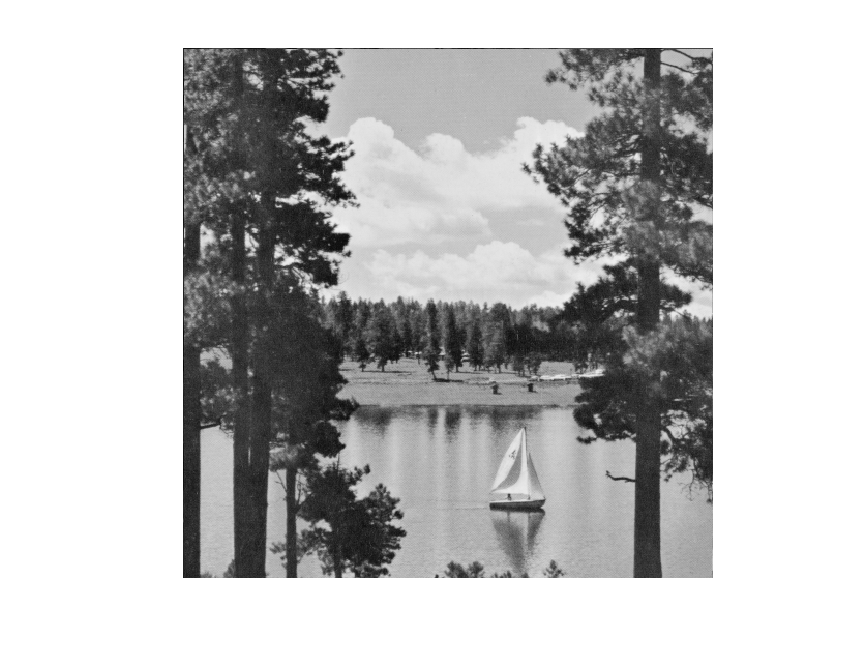

grayDsp = rgb2gray(rgbImage);
imshow(grayDsp)

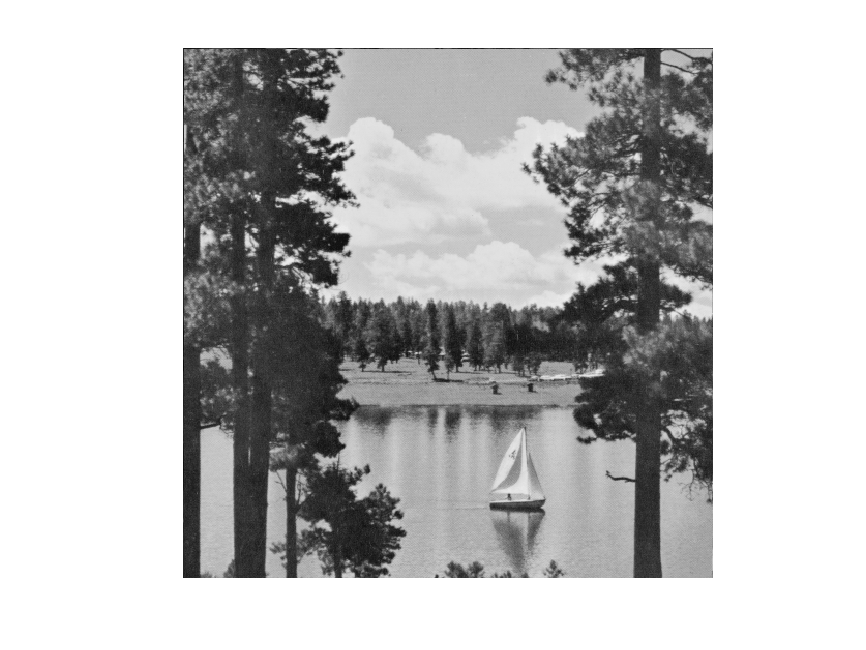

[rows, cols, ~] = size(rgbImage);
grayShifting = zeros(rows, cols, 'uint8');
for i = 1:rows
    for j = 1:cols
        sum = 0;

        R = uint8(rgbImage(i, j, 1));
        R = bitshift(R,-2);
        sum = sum + R;
        R = bitshift(R,-3);
        sum = sum + R;
        R = bitshift(R,-1);
        sum = sum + R;

        G = uint8(rgbImage(i, j, 2)); 
        G = bitshift(G,-1);
        sum = sum + G;
        G = bitshift(G,-3);
        sum = sum + G;
        G = bitshift(G,-2);
        sum = sum + G;
        G = bitshift(G,-1);
        sum = sum + G;

        B = uint8(rgbImage(i, j, 3));
        B = bitshift(B,-4);
        sum = sum + B;
        B = bitshift(B,-1);
        sum = sum + B;
        B = bitshift(B,-1);
        sum = sum + B;
        B = bitshift(B,-2);
        sum = sum + B;
        
        sum = sum + 5;

        grayShifting(i, j) = sum;
    end
end
imshow(grayShifting)

[peaksnr, snr] = psnr(grayDsp, grayShifting);
fprintf('\n The Peak-SNR value is %0.4f dB', peaksnr);


 The Peak-SNR value is 46.0225 dB

fprintf('\n The SNR value is %0.4f dB', snr);


 The SNR value is 40.8646 dB